clear all;
clc;
close all;

## **3.1 GP Complexity **

Nd = [10,15,20];
hyp = [0.05, 1];

computation_time = zeros(length(Nd), 1);
timing_data = struct('K_train', zeros(length(Nd), 1), ...
                     'K_cross', zeros(length(Nd), 1), ...
                     'K_test', zeros(length(Nd), 1), ...
                     'InverseK', zeros(length(Nd), 1), ...
                     'Multiplications', zeros(length(Nd), 1));

for i = 1:length(Nd)
    [X, y, Xstar] = getdata(Nd(i), hyp);

    % Call the modified GPregression function and measure timings
    [Mu, Sigma,Kernel, timing] = GPregression(X, y, Xstar, hyp);

    % Store each part's timing in the respective arrays
    timing_data.K_train(i) = timing.K_train;
    timing_data.K_cross(i) = timing.K_cross;
    timing_data.K_test(i) = timing.K_test;
    timing_data.InverseK(i) = timing.InverseK;
    timing_data.Multiplications(i) = timing.Multiplications;

    % Total computation time
    computation_time(i) = timing.K_train + timing.K_cross + timing.K_test + ...
                          timing.InverseK + timing.Multiplications;

    fprintf('Elapsed time for Nd = %d: %.6f seconds\n', Nd(i), computation_time(i));
end

Elapsed time for Nd = 10: 1.378399 seconds
Elapsed time for Nd = 15: 10.604813 seconds
Elapsed time for Nd = 20: 56.056810 seconds


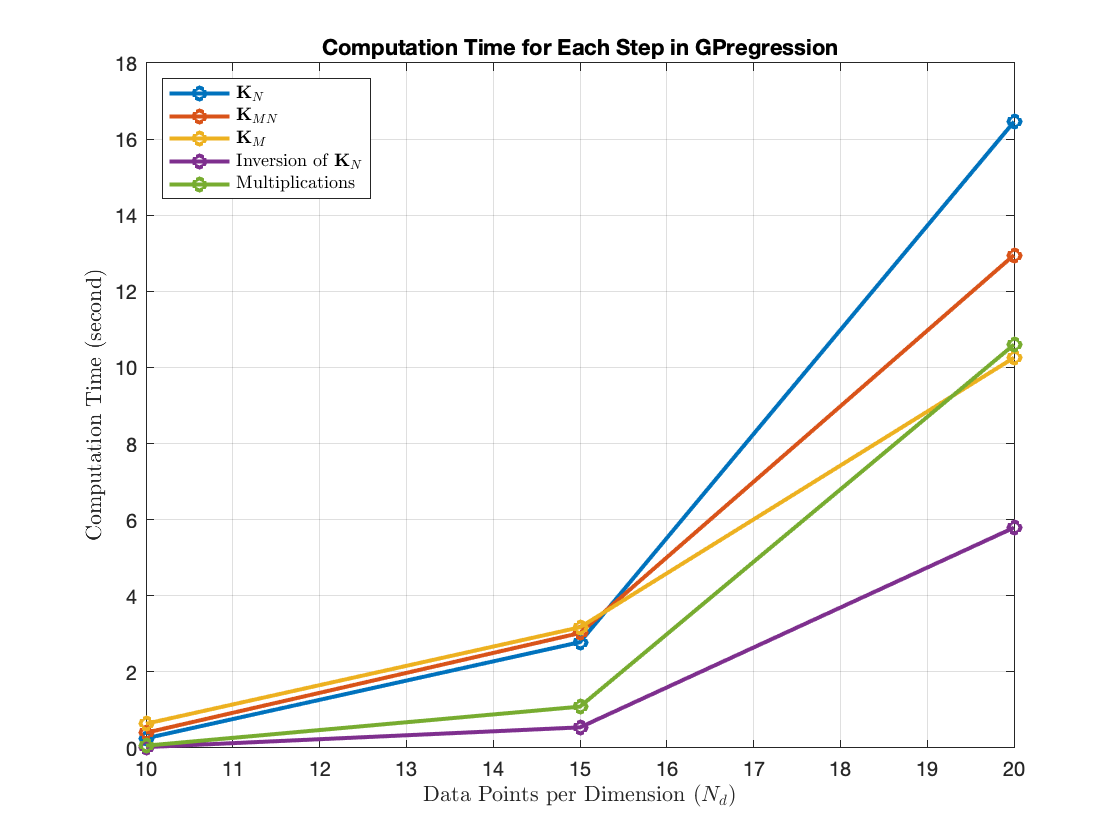

% Plot all the timings
figure;
plot(Nd, timing_data.K_train, '-o', 'LineWidth', 2); hold on;
plot(Nd, timing_data.K_cross, '-o', 'LineWidth', 2);
plot(Nd, timing_data.K_test, '-o', 'LineWidth', 2);
plot(Nd, timing_data.InverseK, '-o', 'LineWidth', 2);
plot(Nd, timing_data.Multiplications, '-o', 'LineWidth', 2);
hold off;

xlabel('Data Points per Dimension ($N_d$)', 'Interpreter', 'latex');
ylabel('Computation Time (second)', 'Interpreter', 'latex');
title('Computation Time for Each Step in GPregression');
legend({'$\mathbf{K}_{N}$', '$\mathbf{K}_{MN}$', '$\mathbf{K}_{M}$', 'Inversion of $\mathbf{K}_{N}$', 'Multiplications'}, 'Location', 'northwest', 'Interpreter', 'latex');
grid on;

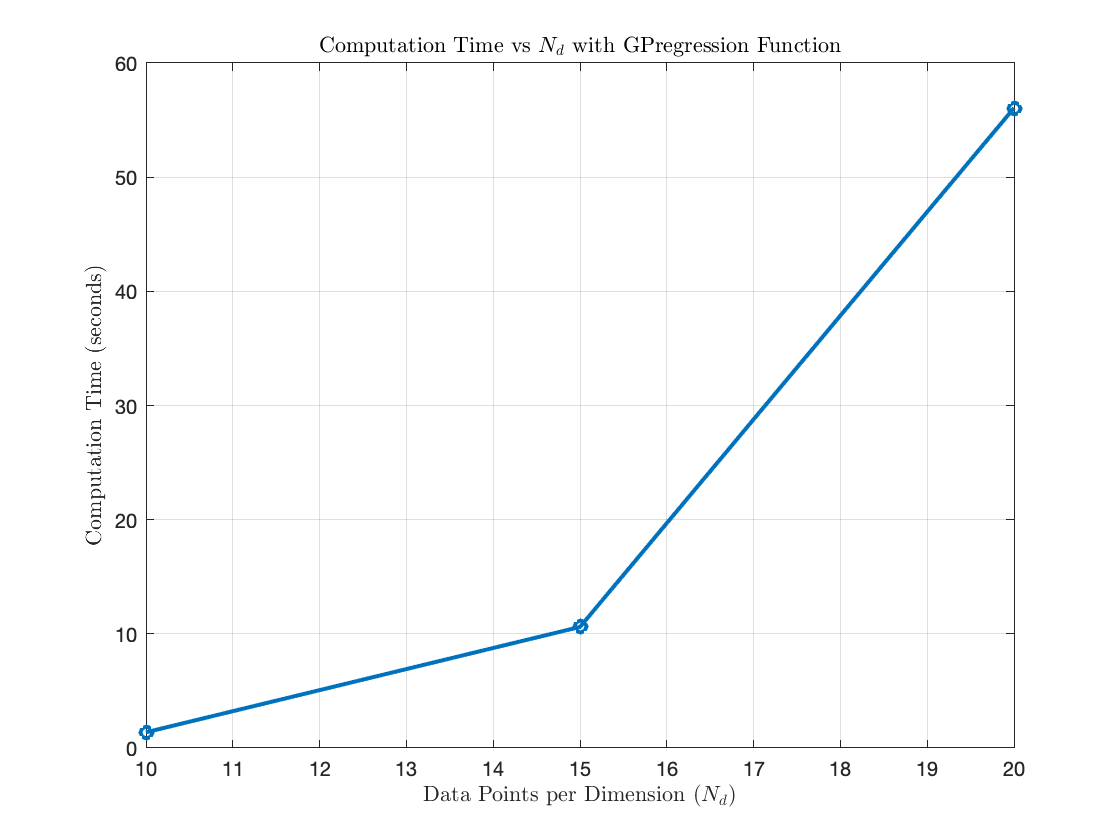

figure;
plot(Nd, computation_time, '-o', 'LineWidth', 2);
xlabel('Data Points per Dimension ($N_d$)', 'Interpreter', 'latex');
ylabel('Computation Time (seconds)','Interpreter', 'latex');
title('Computation Time vs $N_d$ with GPregression Function', 'Interpreter', 'latex');
grid on;

[X, y, Xstar] = getdata(10, hyp);
[Mu, Sigma,Kernel,  ~] = GPregression(X, y, Xstar, hyp);

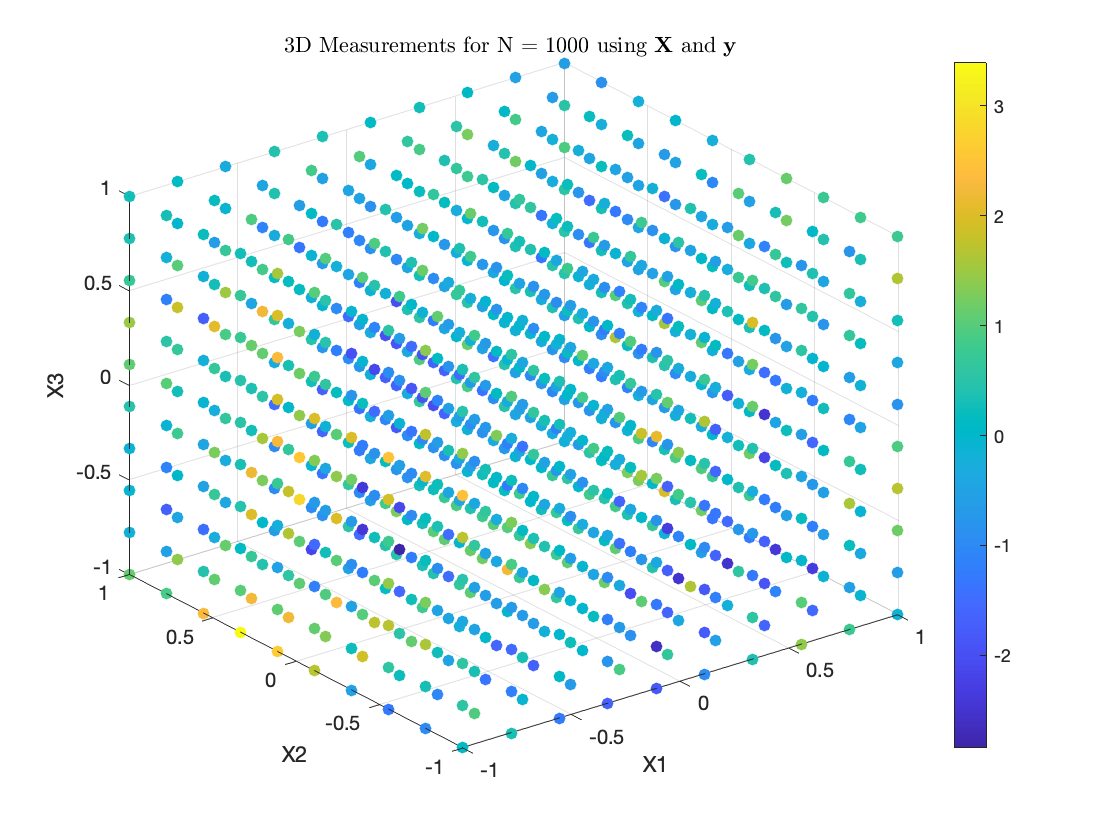

figure;
scatter3(X(:,1), X(:,2), X(:,3), [], y, 'filled');
xlabel('X1');
ylabel('X2');
zlabel('X3');
title('3D Measurements for N = 1000 using $\mathbf{X}$ and $\mathbf{y}$ ', 'Interpreter', 'latex');
colorbar;  

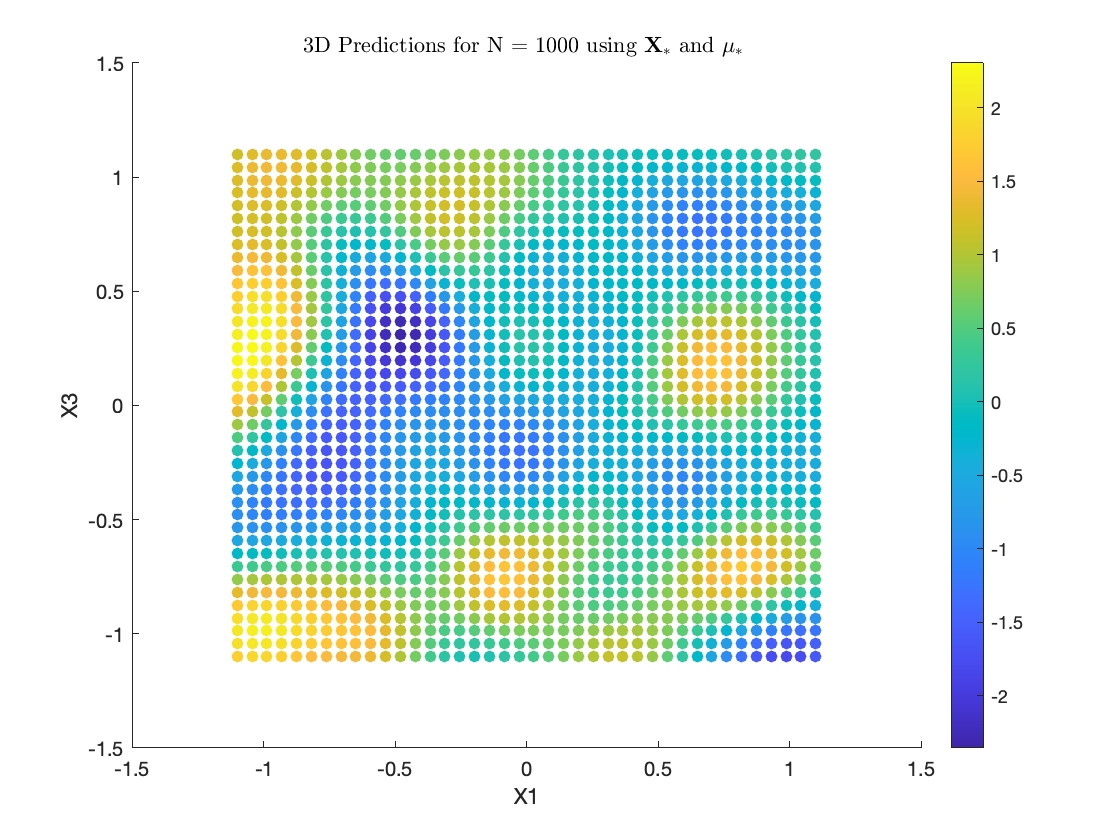


figure;
scatter(Xstar(:,1), Xstar(:,3), [], Mu,'filled');
xlabel('X1');
ylabel('X3');
title('3D Predictions for N = 1000 using $\mathbf{X}_{*}$ and $\mu_{*}$ ', 'Interpreter', 'latex');
colorbar; 

## **3.2 Kernel Matrix as Tensor Train **

In the last exercise, you computed the kernel matrix of a GP. Having the input on a multidimensional grid, you will now investigate, how a low-rank TT can be used to represent the kernel matrix. Use your answers to the questions as well as your insights of the implementations in the main part of your report. 										

1. Transform the kernel matrix K that you computed with 10^3 inputs into a tensor K of size I1 × I2 × I3 × J1 × J2 × J3, where all sizes are equal to 10. Then, compute a TT with the TT-SVD algorithm with ε = 10−10. You can use your or the hidden TT-SVD function from a previous exercise. 				

I1 = 10;
I2 = 10;
I3 = 10;
J1 = 10;
J2 = 10; 
J3 = 10; 

epsilon = 1e-10;

tensor = reshape(Kernel, [I1, I2, I3, J1, J2, J3]);

[tt_cores,rel_error] = hidden_TT_SVD(tensor, epsilon);

2. Now, permute the dimensions of K such that it is I1 ×J1 ×I2 ×J2 ×I3 ×J3. 						

permuted_tensor = permute(tensor, [1, 4, 2, 5, 3, 6]);
size(permuted_tensor)

ans =     10    10    10    10    10    10


3. Reshape K such that the sizes are I1J1 × I2J2 × I3J3 and do another TT-SVD with ε = 10−10. 						

reshaped_tensor = reshape(permuted_tensor, [I1*J1, I2*J2, I3*J3]);
size(reshaped_tensor)

ans =    100   100   100


[tt_cores_for_reshaped,rel_error_for_reshaped] = hidden_TT_SVD(reshaped_tensor, epsilon);

4. What do you observe when comparing the two TTs? Comment on the ranks and on what the sizes I1, I2, I3, J1, J2, J3 represent. Describe the link to a tensor train matrix. 		

% Number of elements in the tensor trains 
noe_tt = TT_numel(tt_cores)

noe_tt = 2020200

noe_tt_for_reshaped = TT_numel(tt_cores_for_reshaped)

noe_tt_for_reshaped = 300

% Compression ratios of the tensor trains 
comp_ratio = noe_tt/numel(tensor)

comp_ratio = 2.0202

comp_ratio_for_reshaped = noe_tt_for_reshaped/numel(tensor)

comp_ratio_for_reshaped = 3.0000e-04


% Sizes of the tensor trains 
TT_size = TT_get_size(tt_cores)

TT_size =            1          10          10
          10          10         100
         100          10        1000
        1000          10         100
         100          10          10
          10          10           1


TT_size_for_reshaped = TT_get_size(tt_cores_for_reshaped)

TT_size_for_reshaped =      1   100     1
     1   100     1
     1   100     1



% Ranks of the tensor trains 
TT_ranks = TT_get_ranks(tt_cores)

TT_ranks =            1
          10
         100
        1000
         100
          10
           1


TT_ranks_for_reshaped = TT_get_ranks(tt_cores_for_reshaped)

TT_ranks_for_reshaped =      1
   100
   100
     1


## **3.3 Kernel Matrix as Kronecker Product **

For inputs that lie on a multidimensional grid, the dimensions become independent of each other the kernel matrix can be written as a Kronecker product over dimensions, as described in [2]. 

1. Compute a kernel matrix per dimension with 10 data points per dimension with Equation (5.4) of [2], using one term of the product per dimension. Note that the inputs per dimension are the coordinates per dimension, e.g. coordX1 = linspace(-1,1,10). 	

coordX1 = linspace(-1, 1, 10);
coordX2 = linspace(-1, 1, 10);
coordX3 = linspace(-1, 1, 10);

sf_2 = hyp(2);
l_2 = hyp(1);

N = length(coordX1);

k = @(x1, x2) sf_2 * exp(-sum((x1 - x2).^2) / (2 * l_2));

K1 = zeros(N, N);
K2 = zeros(N, N);
K3 = zeros(N, N);

for i = 1:N
    for j = 1:N
        K1(i, j) = k(coordX1(i), coordX1(j));
        K2(i, j) = k(coordX2(i), coordX2(j));
        K3(i, j) = k(coordX3(i), coordX3(j));
    end
end


2. Compute the Kronecker product K3 ⊗ K2 ⊗ K1. You can test your result by comparing it to K that is returned by the function GPregression. 	

K_total = kron(kron(K3, K2), K1);
size(K_total)

ans =         1000        1000


norm_original = norm(Kernel, 'fro');
norm_kron = norm(K_total, 'fro');
fprintf('Frobenius norm of original kernel: %f\n', norm_original);

Frobenius norm of original kernel: 70.178812


fprintf('Frobenius norm of Kronecker product kernel: %f\n', norm_kron);

Frobenius norm of Kronecker product kernel: 70.178812


K_train_normalized = Kernel / norm_original;
K_kron_normalized = K_total / norm_kron;

difference = K_train_normalized - K_kron_normalized;
difference_norm = norm(difference, 'fro');

fprintf('Frobenius norm of the difference after normalizing: %f\n', difference_norm);

Frobenius norm of the difference after normalizing: 0.000000


3. Compute the inverse of K, given by K−1 = K−1 ⊗ K−1 ⊗ K−1.

K1_inv = inv(K1);
K2_inv = inv(K2);
K3_inv = inv(K3);

K_inv_total = kron(kron(K3_inv, K2_inv), K1_inv);

4. Comment on how to transform the Kronecker product into a tensor train. Comment on the size of each TT-core and why this format decreases the computational complexity. 		

K_matrices = {K1,K2,K3};
D = length(K_matrices);

K_total = K_matrices{D};
for d = D-1:-1:1
    K_total = kron(K_total, K_matrices{d});
end

I_sizes = zeros(1, length(K_matrices));  % Row sizes
J_sizes = zeros(1, length(K_matrices));  % Column sizes
for i = 1:length(K_matrices)
    I_sizes(i) = size(K_matrices{i}, 1);
    J_sizes(i) = size(K_matrices{i}, 2); 
end

% Reshape K_total into a high-dimensional tensor according to the row and column sizes
tensor_reshaped = reshape(K_total, [I_sizes, J_sizes]);

% Permute dimensions to group corresponding rows and columns together
permute_order = reshape([1:D; D+1:2*D], 1, []);  % Interleave row and column indices
tensor_permuted = permute(tensor_reshaped, permute_order);

% Reshape into the final form I1*J1 x I2*J2 x ... x ID*JD for TT-SVD
final_shape = zeros(1, length(I_sizes));
for i = 1:length(I_sizes)
    final_shape(i) = I_sizes(i) * J_sizes(i);
end
reshaped_tensor = reshape(tensor_permuted, final_shape);

% Apply TT-SVD to the reshaped tensor
[tt_cores, rel_error] = hidden_TT_SVD(reshaped_tensor, epsilon);

noe_tt = TT_numel(tt_cores)

noe_tt = 300

comp_ratio = noe_tt/numel(tensor)

comp_ratio = 3.0000e-04

TT_size = TT_get_size(tt_cores)

TT_size =      1   100     1
     1   100     1
     1   100     1


5. Draw a diagram of the Kronecker product of matrices in terms of a 3 core tensor train matrix. Hint: check the lecture notes how the indices behave in the Kronecker product. 						

%

## **3.4 GPs with Tensor Train **								

1. Implement a new function KronGPregression that receives as an input the kernel matrices per dimen- sion, as well as the data X,y and X∗. Exploit the Kronecker algebra to improve the scalability of the GP regression. 	

K_matrices = {K1,K2,K3};

2. Call the new function for N = 10^3 , 15^3 , 20^3 and time with tic and toc. 	

Nd = [10,15,20];

Test = true;

% Original function results initialization
computation_time_orig = zeros(length(Nd), 1);
Mu_orig_list = cell(length(Nd), 1);
Sigma_orig_list = cell(length(Nd), 1);
timing_data_orig = struct('K_train', zeros(length(Nd), 1), ...
                     'K_cross', zeros(length(Nd), 1), ...
                     'K_test', zeros(length(Nd), 1), ...
                     'InverseK', zeros(length(Nd), 1), ...
                     'Multiplications', zeros(length(Nd), 1));

% Adjusted function results initialization
computation_time_kron = zeros(length(Nd), 1);
Mu_kron_list = cell(length(Nd), 1);
Sigma_kron_list = cell(length(Nd), 1);
timing_data_kron = struct('K_train', zeros(length(Nd), 1), ...
                     'K_cross', zeros(length(Nd), 1), ...
                     'K_test', zeros(length(Nd), 1), ...
                     'InverseK', zeros(length(Nd), 1), ...
                     'Multiplications', zeros(length(Nd), 1));

% Testing and storing results for multiple Nd's
for i = 1:length(Nd)
    [X, y, Xstar] = getdata(Nd(i), hyp);
    
    coordX1 = linspace(-1, 1, Nd(i));
    coordX2 = linspace(-1, 1, Nd(i));
    coordX3 = linspace(-1, 1, Nd(i));
    X_cell = {coordX1, coordX2, coordX3};
    if Test
        [Mu_orig_list{i}, Sigma_orig_list{i},~, timing] = GPregression(X, y, Xstar, hyp);
        
        timing_data_orig.K_train(i) = timing.K_train;
        timing_data_orig.K_cross(i) = timing.K_cross;
        timing_data_orig.K_test(i) = timing.K_test;
        timing_data_orig.InverseK(i) = timing.InverseK;
        timing_data_orig.Multiplications(i) = timing.Multiplications;
        computation_time_orig(i) = timing.K_train + timing.K_cross + timing.K_test + ...
                          timing.InverseK + timing.Multiplications;
        fprintf('Elapsed time for original function Nd = %d: %.6f seconds\n', Nd(i), computation_time_orig(i));    

    end

    [Mu_kron_list{i}, Sigma_kron_list{i}, timing] = KronGPregression(X_cell, X, y, Xstar, hyp);
    
    timing_data_kron.K_train(i) = timing.K_train;
    timing_data_kron.K_cross(i) = timing.K_cross;
    timing_data_kron.K_test(i) = timing.K_test;
    timing_data_kron.InverseK(i) = timing.InverseK;
    timing_data_kron.Multiplications(i) = timing.Multiplications;

    % Total computation time
    computation_time_kron(i) = timing.K_train + timing.K_cross + timing.K_test + ...
                          timing.InverseK + timing.Multiplications;

    fprintf('Elapsed time for updated function Nd = %d: %.6f seconds\n\n', Nd(i), computation_time_kron(i));    
end

Elapsed time for original function Nd = 10: 1.572941 seconds


Elapsed time for updated function Nd = 10: 0.557863 seconds



Elapsed time for original function Nd = 15: 11.375616 seconds


Elapsed time for updated function Nd = 15: 4.013565 seconds



Elapsed time for original function Nd = 20: 58.095866 seconds


Elapsed time for updated function Nd = 20: 17.772901 seconds



if timing_data_orig.K_train ~= 0
    for i = 1:length(Nd)
        % Compute the norm of the difference for Mu
        Mu_diff_norm = norm(Mu_orig_list{i} - Mu_kron_list{i},'fro') /numel(Mu_kron_list{i});
        fprintf('Norm of difference in Mu for Nd = %d: %.6e\n', Nd(i), Mu_diff_norm);
    
        % Compute the norm of the difference for Sigma
        Sigma_diff_norm = norm(Sigma_orig_list{i} - Sigma_kron_list{i}, 'fro')/numel(Sigma_kron_list{i});
        fprintf('Norm of difference in Sigma for Nd = %d: %.6e\n', Nd(i), Sigma_diff_norm);
       
        fprintf('__')
    end
end

Norm of difference in Mu for Nd = 10: 2.213069e-03


Norm of difference in Sigma for Nd = 10: 1.919897e-06


__

Norm of difference in Mu for Nd = 15: 1.831250e-03


Norm of difference in Sigma for Nd = 15: 3.756213e-07


__

Norm of difference in Mu for Nd = 20: 1.164120e-03


Norm of difference in Sigma for Nd = 20: 1.933735e-07


__

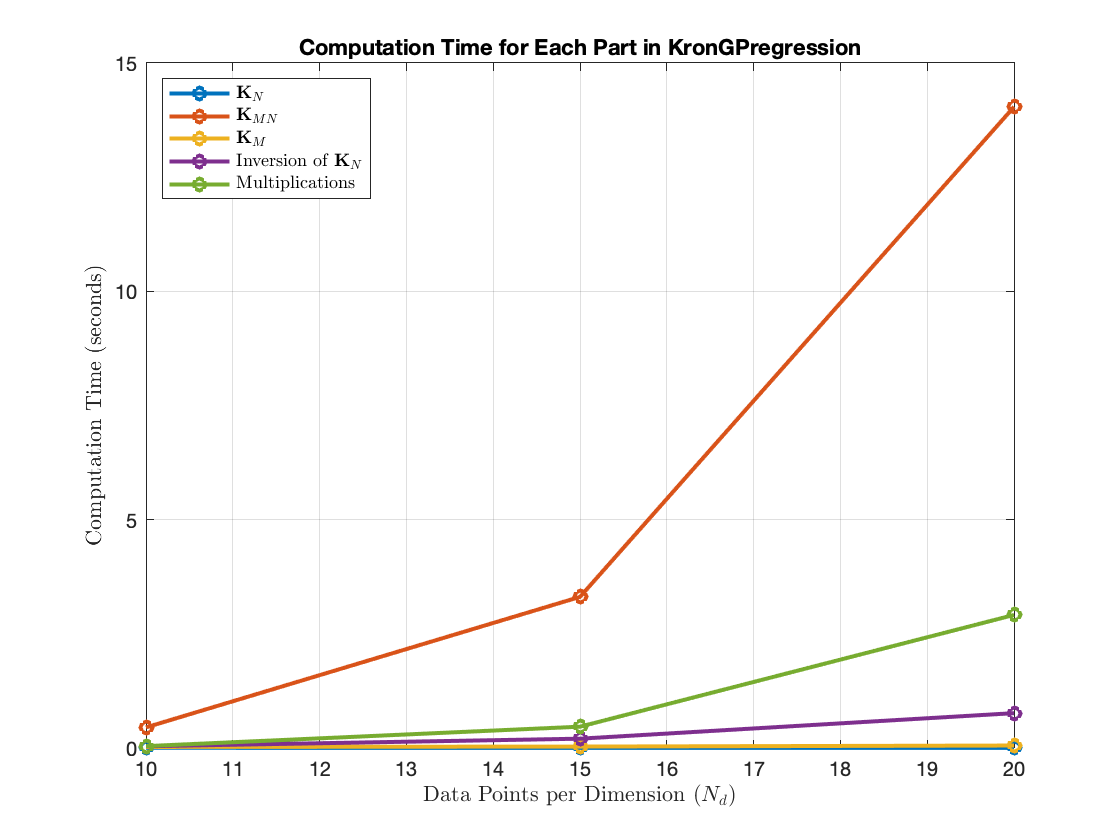

% Plot all the timings
figure;
plot(Nd, timing_data_kron.K_train, '-o', 'LineWidth', 2); hold on;
plot(Nd, timing_data_kron.K_cross, '-o', 'LineWidth', 2);
plot(Nd, timing_data_kron.K_test, '-o', 'LineWidth', 2);
plot(Nd, timing_data_kron.InverseK, '-o', 'LineWidth', 2);
plot(Nd, timing_data_kron.Multiplications, '-o', 'LineWidth', 2);
hold off;

xlabel('Data Points per Dimension ($N_d$)', 'Interpreter', 'latex');
ylabel('Computation Time (seconds)','Interpreter', 'latex');
title('Computation Time for Each Part in KronGPregression');

legend({'$\mathbf{K}_{N}$', '$\mathbf{K}_{MN}$', '$\mathbf{K}_{M}$', 'Inversion of $\mathbf{K}_{N}$', 'Multiplications'}, 'Location', 'northwest', 'Interpreter', 'latex');
grid on;

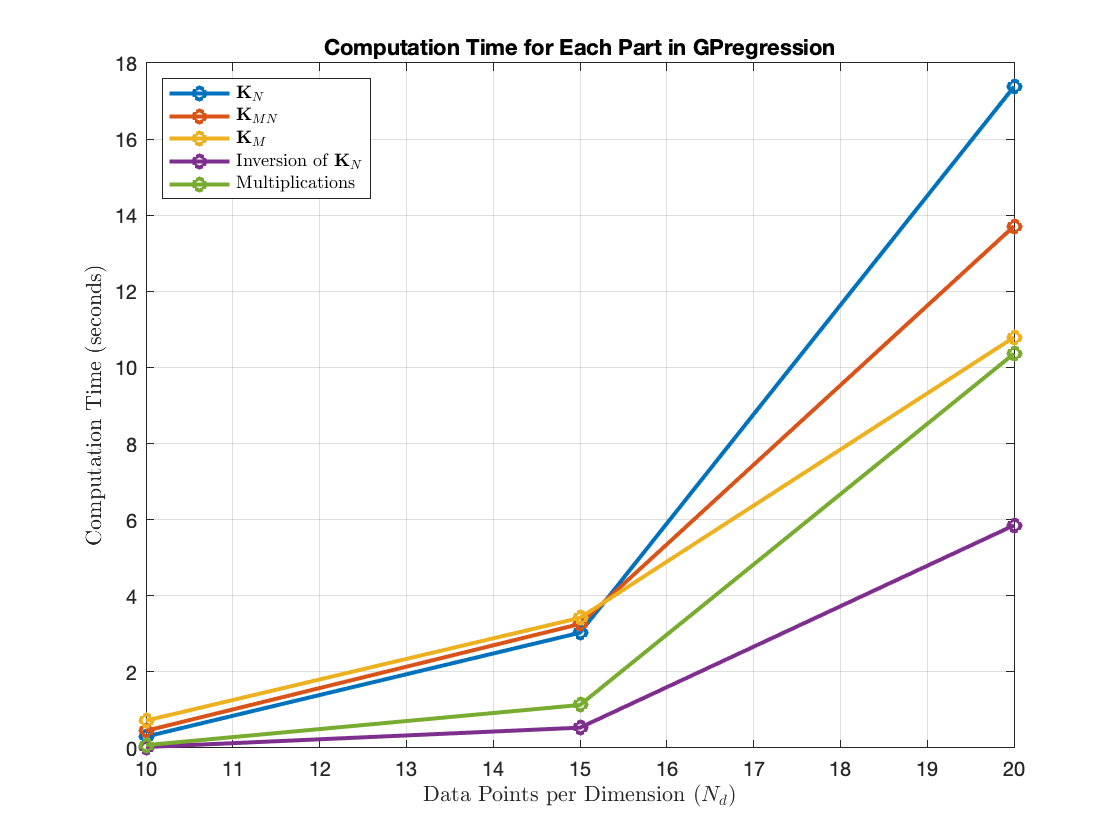

if timing_data_orig.K_train ~= 0
    plot(Nd, timing_data_orig.K_train, '-o', 'LineWidth', 2); hold on;
    plot(Nd, timing_data_orig.K_cross, '-o', 'LineWidth', 2);
    plot(Nd, timing_data_orig.K_test, '-o', 'LineWidth', 2);
    plot(Nd, timing_data_orig.InverseK, '-o', 'LineWidth', 2);
    plot(Nd, timing_data_orig.Multiplications, '-o', 'LineWidth', 2);
    hold off;
    
    xlabel('Data Points per Dimension ($N_d$)', 'Interpreter', 'latex');
    ylabel('Computation Time (seconds)','Interpreter', 'latex');
    title('Computation Time for Each Part in GPregression');
    legend({'$\mathbf{K}_{N}$', '$\mathbf{K}_{MN}$', '$\mathbf{K}_{M}$', 'Inversion of $\mathbf{K}_{N}$', 'Multiplications'}, 'Location', 'northwest', 'Interpreter', 'latex');
    grid on;
end

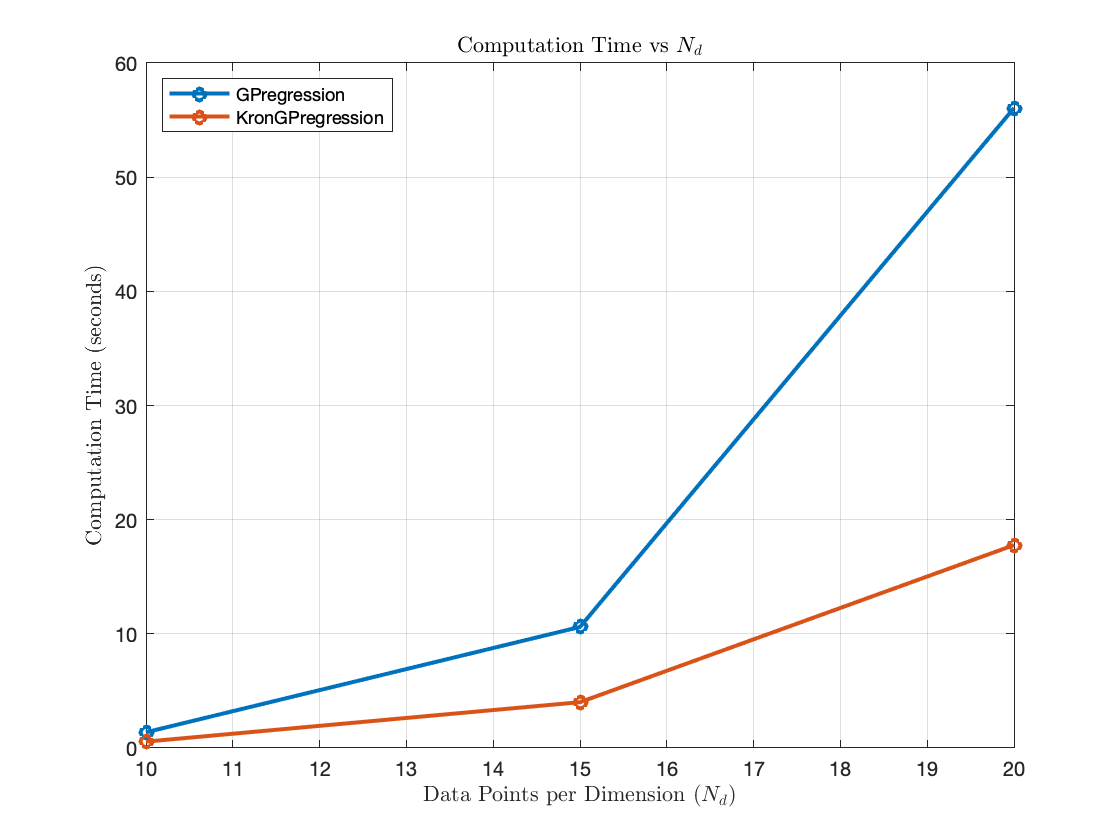


figure;
plot(Nd, computation_time, '-o', 'LineWidth', 2);
hold on;
plot(Nd, computation_time_kron, '-o', 'LineWidth', 2);

xlabel('Data Points per Dimension ($N_d$)', 'Interpreter', 'latex');
ylabel('Computation Time (seconds)','Interpreter', 'latex');
title('Computation Time vs $N_d$', 'Interpreter', 'latex');
legend({'GPregression','KronGPregression'}, 'Location', 'northwest')
grid on;

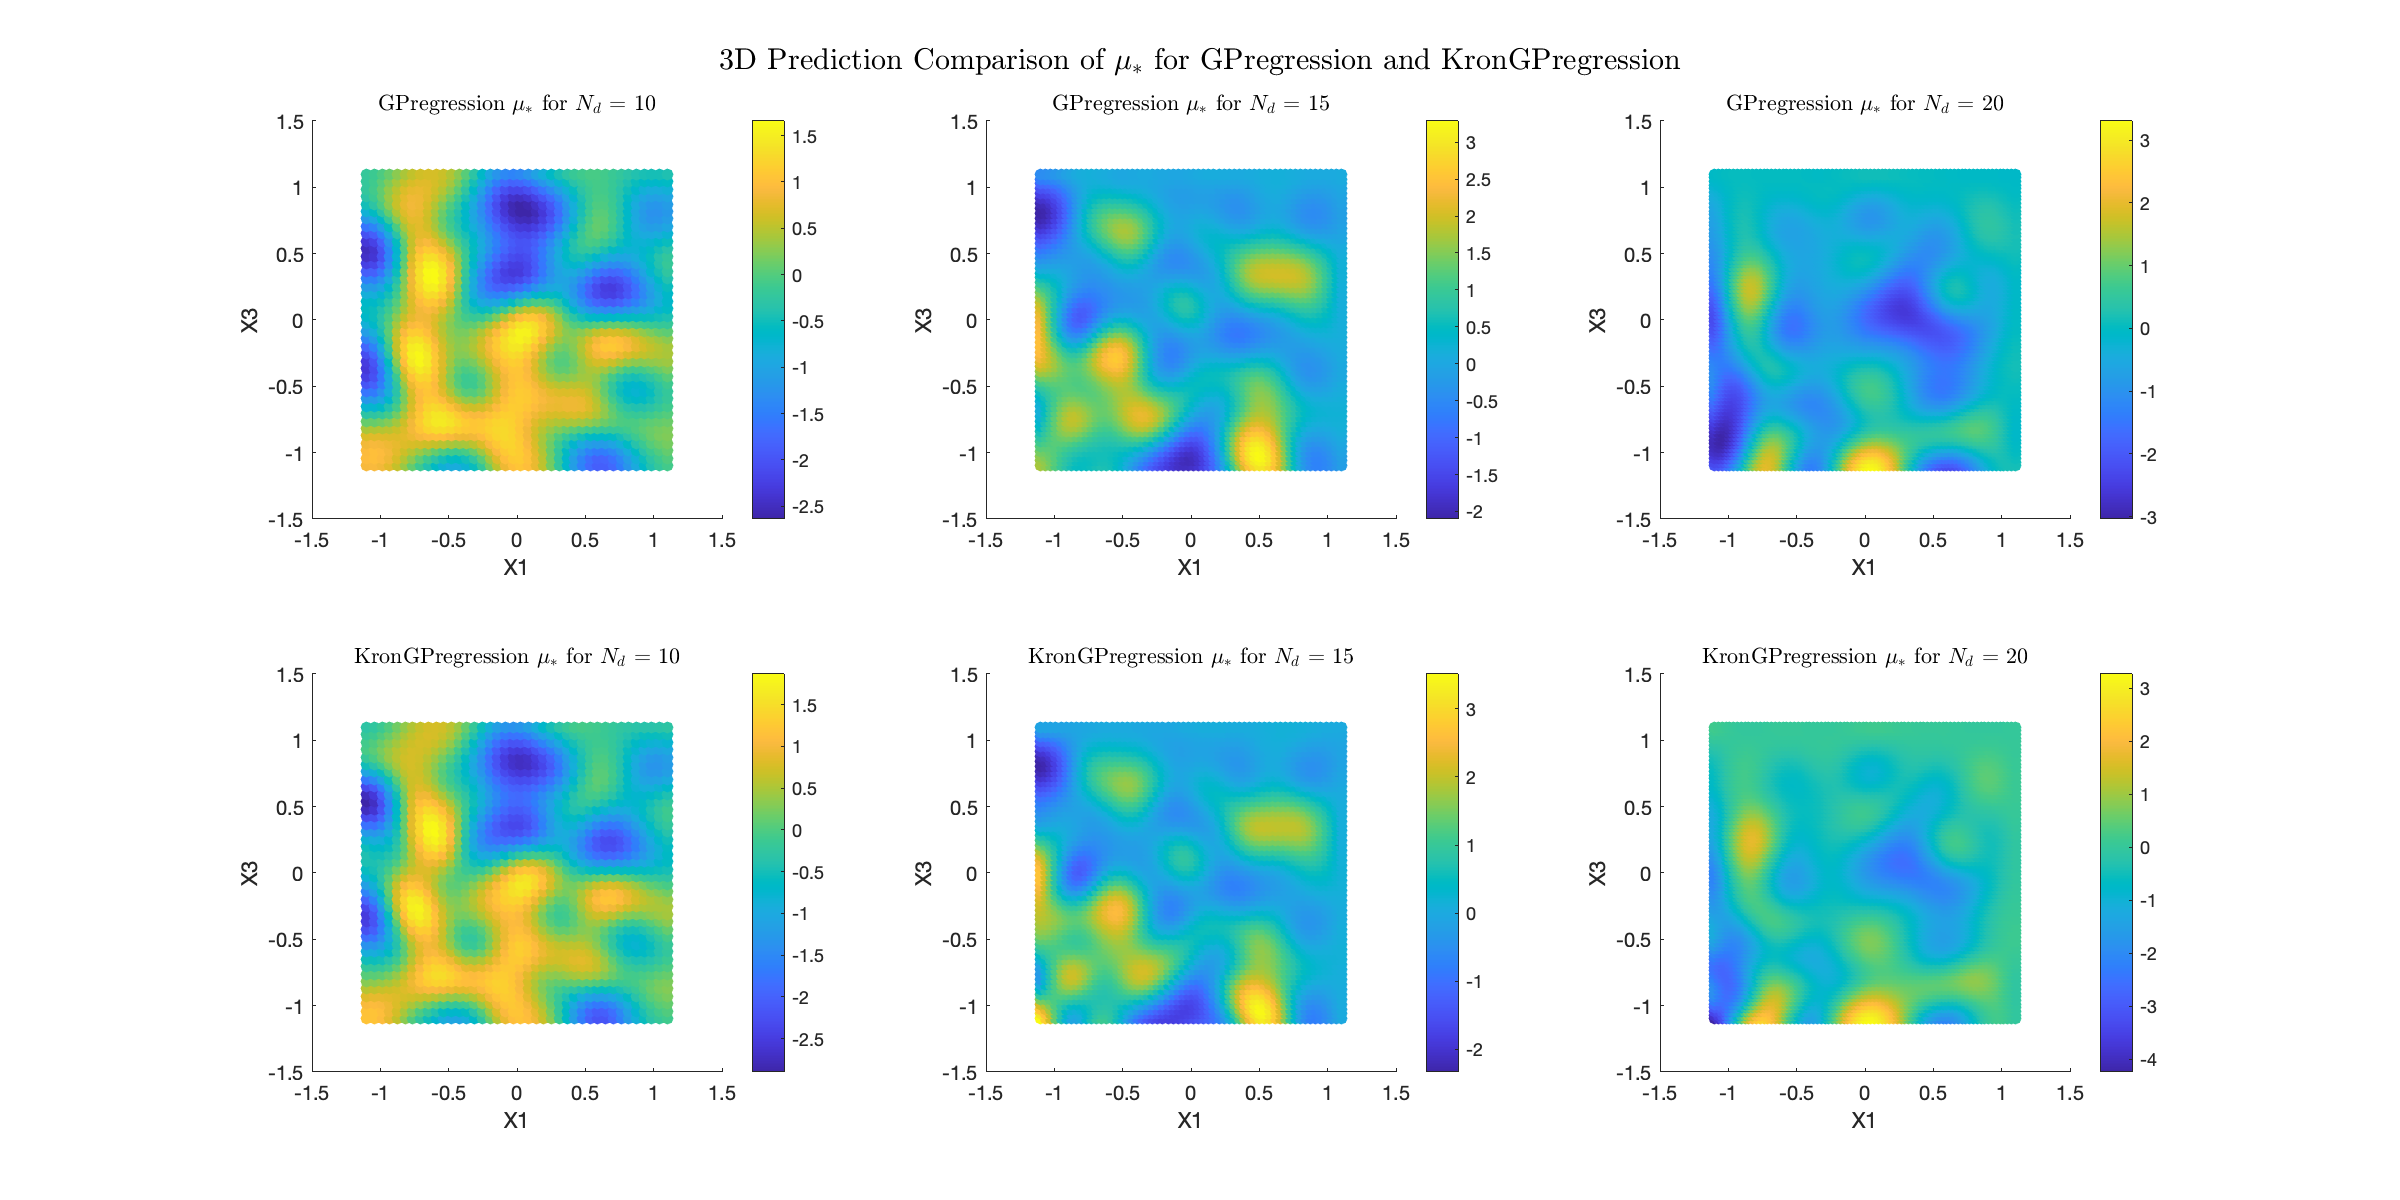


% figure;
figure('Position', [100, 100, 1200, 600]);
% Plot the original Mu data in the top row (1st, 2nd, 3rd subplots)
for j = 1:3
    [X1,X2,X3] = meshgrid(linspace(-1.1,1.1,4*Nd(j)),linspace(0,0,1),linspace(-1.1,1.1,4*Nd(j)));
    Xstar      = [X1(:),X2(:),X3(:)];
    subplot(2, 3, j); % Top row for original Mu
    scatter(Xstar(:,1), Xstar(:,3), [], Mu_orig_list{j}, 'filled');
    xlabel('X1');
    ylabel('X3');
    title(['GPregression $\mu_{*}$ for $N_d$ = ', num2str(Nd(j))], 'Interpreter', 'latex');
    colorbar;
end

% Plot the kron Mu data in the bottom row (4th, 5th, 6th subplots)
for j = 1:3
    [X1,X2,X3] = meshgrid(linspace(-1.1,1.1,4*Nd(j)),linspace(0,0,1),linspace(-1.1,1.1,4*Nd(j)));
    Xstar      = [X1(:),X2(:),X3(:)];
    subplot(2, 3, j + 3); % Bottom row for Mu_kron
    scatter(Xstar(:,1), Xstar(:,3), [], Mu_kron_list{j}, 'filled');
    xlabel('X1');
    ylabel('X3');
    title(['KronGPregression $\mu_{*}$ for $N_d$ = ', num2str(Nd(j))], 'Interpreter', 'latex');
    colorbar;
end

sgtitle('3D Prediction Comparison of $\mu_{*}$ for GPregression and KronGPregression', 'Interpreter', 'latex');

3. Do you see a speed up compared to the original function? 				

% Probably yes